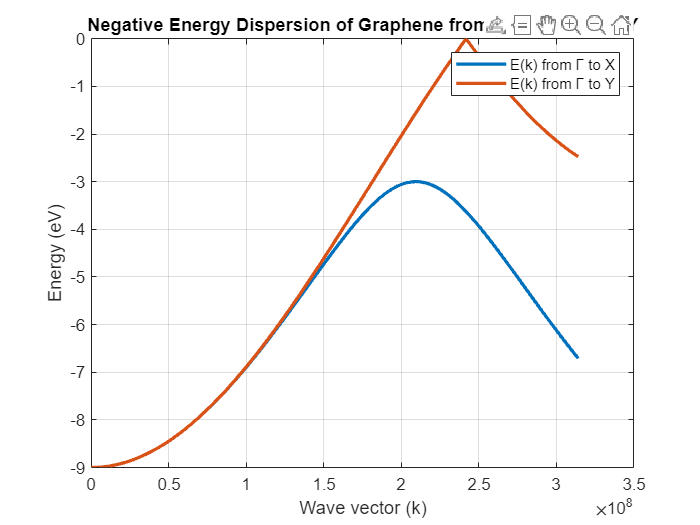

% Define the number of points, or the lattice size (just a big number)
N = 1000;
a = 10e-9; % Lattice constant a, equals L=10nm for simplicity

% Define the energy dispersion function for graphene
t = 3.0; % Hopping energy in eV
energy_dispersion = @(kx, ky, sign) sign * t * sqrt(1 + 4 * cos(3 * a * kx / 2) .* cos(sqrt(3) * a * ky / 2) + ...
                                       4 * cos(sqrt(3) * a * ky / 2).^2);

% Define k values with increments of (2pi*n)/(Na)
k_values = (2 * pi * (0:N/2)) / (N * a);

% Calculate the energy dispersion along the k-path from Gamma to X and Gamma to Y
E_Gamma_X = energy_dispersion(k_values, zeros(size(k_values)), -1);
E_Gamma_Y = energy_dispersion(zeros(size(k_values)), k_values, -1);

% Create the plot
figure;

% Plot Gamma to X
plot(k_values, E_Gamma_X, 'LineWidth', 2);
hold on;

% Plot Gamma to Y
plot(k_values, E_Gamma_Y, 'LineWidth', 2);

% Labeling the axes and the plot
xlabel('Wave vector (k)');
ylabel('Energy (eV)');
title('Negative Energy Dispersion of Graphene from Γ to X and Γ to Y');
legend('E(k) from Γ to X', 'E(k) from Γ to Y');

% Add grid to the plot for better readability
grid on;

% Show the plot
hold off;